ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


ans =   1×2 Layer array with layers:

     1   'loss3-classifier'   Fully Connected         1000 fully connected layer
     2   'output'             Classification Output   crossentropyex with 'tench' and 999 other classes

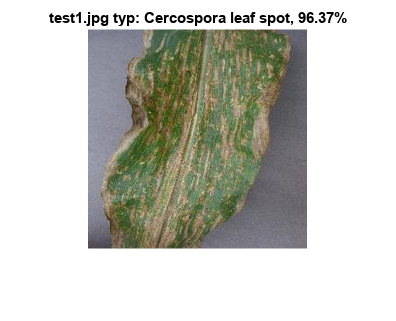

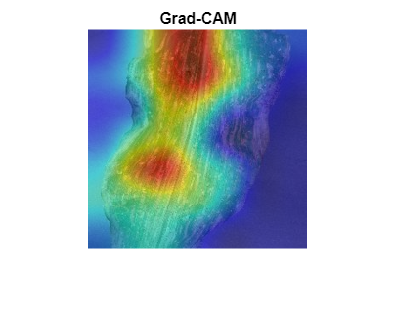

Unrecognized function or variable 'ax'.

% Take in data

%unzip('MerchData.zip');
imds = imageDatastore('PlantVillage-Dataset', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');
net = googlenet;
net.Layers(1)
inputSize = net.Layers(1).InputSize;
lgraph = layerGraph(net);
[learnableLayer,classLayer] = findLayersToReplace(lgraph);
[learnableLayer,classLayer] 
numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);
figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])
layers = lgraph.Layers;
connections = lgraph.Connections;

layers(1:10) = freezeWeights(layers(1:10));
lgraph = createLgraphUsingConnections(layers,connections);
pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);
miniBatchSize = 50;
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'ExecutionEnvironment', 'gpu', ...
    'Plots','training-progress');
net = trainNetwork(augimdsTrain,lgraph,options);
[YPred,probs] = classify(net,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)
idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end
figure(Units="normalized",Position=[0.2 0.2 0.4 0.4]);
cm = confusionchart(imdsValidation.Labels,YPred);
cm.Title = "Confusion Matrix for Validation Data";
cm.ColumnSummary = "column-normalized";
cm.RowSummary = "row-normalized";

outputdr = "trainedmodel"
outputfl = fullfile(outputdr,"trainedNet.mat");
save(outputfl,"net")


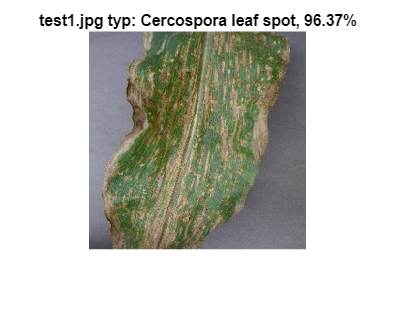

load ('./trainedmodel/trainedNet.mat', "net")
filename = "test1.jpg";
im = imread(filename);
I = imresize(im, [224 224]);
[label,scores] = classify(net,I);
imshow(I)
title(string(filename)+ " typ: " +  string(label) + ", " + num2str(100*max(scores),4) + "%");

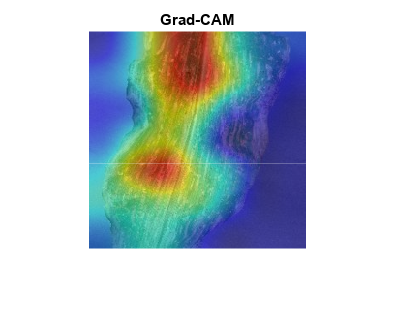

figure;
map = gradCAM(net,I,label);
imshow(I);
hold on;
imagesc(map,'AlphaData',0.5);
colormap jet
hold off;
title("Grad-CAM");
f = getframe;

f = f.cdata

f = 224×224×3 uint8 array
f(:,:,1) =

    61    61    61    62    62    63    64    62    62    63    65    65    64    62    64    64    63    62    61    61    61    58    58    58    58    59    59    60    56    57    58    59    59    59    59    61    62    62    60    58    58    59    60    60    60    61    61    62    67    73    78    84    91    99   104   110   122   141   157   154   157   164   180   194   194   189   180   171   167   165   166   164   162   160   159   158   159   157   160   159   162   158   160   161   164   164   166   167   164   168   174   171   161   155   151   141   133   135   129   133   134   138   131   127   147   143   147   124   120   121   140   130   129   141   141   147   149   158   154   161   174   178   195   201   197   190   189   194   190   201   189   182   187   186   183   192   177   164   160   149   117   104   107    96   102   108    98    84    90    83    63    61    48    41    39    38    46    52    49    48  

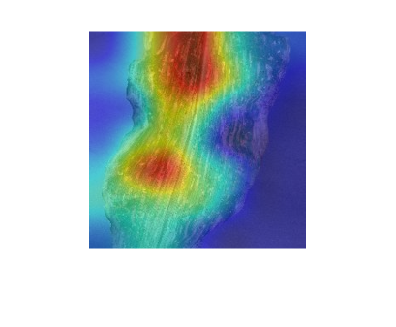

imshow(f)